# Activity 7: Color Science

## Part 1 of 3: Trichromaticity of Color Mixture

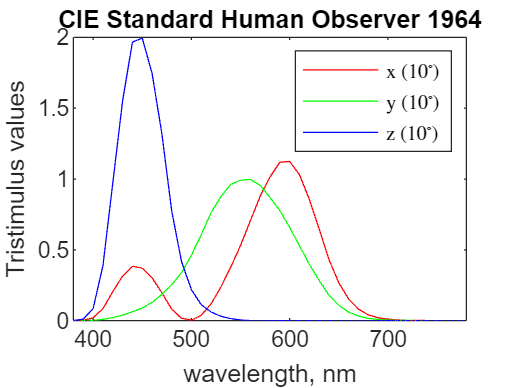

clear;
%extracting data from excel file 
%for CIE Standard Human Observer 1964
wavelengths = readmatrix('CIE Standard Human Observer 1964.xlsx', 'Range', 'A2:A42');
x_bar = readmatrix('CIE Standard Human Observer 1964.xlsx', 'Range', 'B2:B42');
y_bar = readmatrix('CIE Standard Human Observer 1964.xlsx', 'Range', 'C2:C42');
z_bar = readmatrix('CIE Standard Human Observer 1964.xlsx', 'Range', 'D2:D42');

%plotting the tristimulus curves
figure;
plot(wavelengths, x_bar, 'r');
hold on;
plot(wavelengths, y_bar, 'g');
plot(wavelengths, z_bar, 'b');
legend({'x (10$^\circ$)','y (10$^\circ$)', 'z (10$^\circ$)'  }, 'Interpreter', 'latex');
xlabel('wavelength, nm');
ylabel('Tristimulus values');
title('CIE Standard Human Observer 1964');
xlim([380 780]);
hold off;

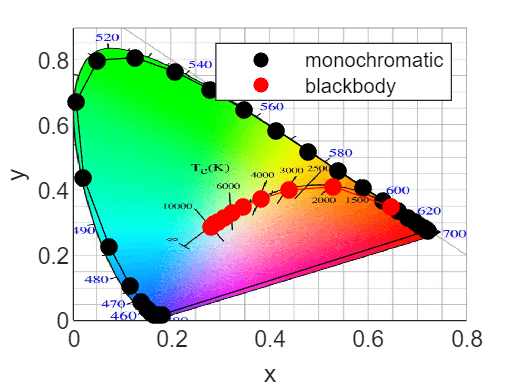

%Solving for CIE-xy chromaticities for monochromatic lights(dirac delta)
%storing all x and y values
all_x = zeros(1,41);
all_y = zeros(1,41);
all_z = zeros(1,41);
for i = 1:41
    SUM = x_bar(i,1) + y_bar(i,1) + z_bar(i,1);
    all_x(1,i) = x_bar(i,1) / SUM;
    all_y(1,i) = y_bar(i,1) / SUM;
    all_z(1,i) = z_bar(i,1) / SUM;
end

%Getting the Planckian Locus
% Constants
T_range = 1000:1000:10000;  % Temperature range from 1000K to 10000K
h = 6.626e-34;  % Planck constant
c = 3e8;  % Speed of light
k = 1.38e-23;  % Boltzmann constant

% Calculate CIE-xy chromaticities for each temperature
xy_chromaticities = zeros(length(T_range), 2);

for i = 1:length(T_range)
    T = T_range(i);  % Current temperature
    lambda = 380:10:780;  % Wavelength range (visible spectrum: 380nm to 780nm)
    lambda = lambda * 1e-9;  % Convert to meters

    % Calculate spectral radiance per unit wavelength using Planck's law
    B_lambda = (2 * h * c^2) ./ (lambda.^5 .* (exp((h * c) ./ (lambda * k * T)) - 1));

    X = trapz(lambda, B_lambda .* x_bar.');
    Y = trapz(lambda, B_lambda .* y_bar.');
    Z = trapz(lambda, B_lambda .* z_bar.');


    % Calculate xy chromaticity coordinates
    xy_chromaticities(i, 1) = X / (X+Y+Z);
    xy_chromaticities(i, 2) = Y / (X+Y+Z);
end

% Plot on CIE xy chromaticity diagram (embed 1931 with blackbody)
figure;
line_x = [0.181406 0.722222];
line_y = [0.0192744 0.277778];
plot(all_x, all_y, 'k');
sz=50;
ylim([0 0.9]);
xlim([0 0.8]);
ylabel('y');
xlabel('x');
hold on;
img = imread('cie1931 cropped.png'); %picture to embed
image(img, 'XData', [0 0.8], 'YData', [0.9 0]);
% plotChromaticity();
plot(all_x, all_y, 'k');
s = scatter(all_x, all_y, sz, "filled", 'DisplayName', 'monochromatic'); %CIE xy for monochromatic
s.MarkerFaceColor = [0 0 0];
s1 = scatter(xy_chromaticities(:, 1), xy_chromaticities(:, 2), sz, 'filled', 'DisplayName', 'blackbody'); %CIE-xy for blackbody
s1.MarkerFaceColor = 'r';
plot(xy_chromaticities(:, 1), xy_chromaticities(:, 2), 'Color', 'r');
line(line_x, line_y, 'Color', 'k');

% Create legend with only those scatter plots that have a 'DisplayName'
legend_handles = [s, s1];
legend_labels = {s.DisplayName, s1.DisplayName};
legend(legend_handles, legend_labels, 'Location', 'northeast');
hold off;

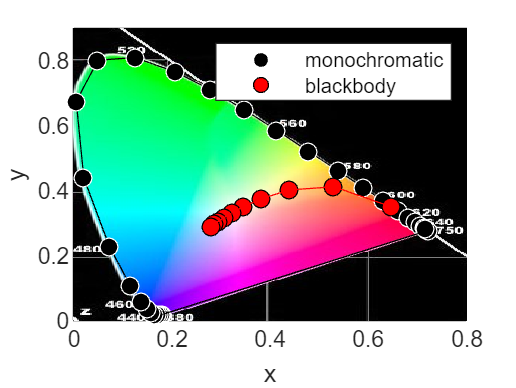

%Using CIE 1964 without Planckian locus
figure;
line_x = [0.181406 0.722222];
line_y = [0.0192744 0.277778];
plot(all_x, all_y, 'k');
sz=50;
ylim([0 0.9]);
xlim([0 0.8]);
ylabel('y');
xlabel('x');
hold on;
img = imread('CIE1964 new - cropped.jpg'); %picture to embed
image(img, 'XData', [0 1], 'YData', [1 0]);
plot(all_x, all_y, 'k');
s = scatter(all_x, all_y, sz, "filled", 'DisplayName', 'monochromatic'); %CIE xy for monochromatic
s.MarkerFaceColor = [0 0 0];
s.MarkerEdgeColor = [1 1 1];
s1 = scatter(xy_chromaticities(:, 1), xy_chromaticities(:, 2), sz, 'filled', 'DisplayName', 'blackbody'); %CIE-xy for blackbody
s1.MarkerFaceColor = 'r';
s1.MarkerEdgeColor = [0 0 0];
line(line_x, line_y, 'Color', 'k');
plot(xy_chromaticities(:, 1), xy_chromaticities(:, 2), 'Color', 'r');

% Create legend with only those scatter plots that have a 'DisplayName'
legend_handles = [s, s1];
legend_labels = {s.DisplayName, s1.DisplayName};
legend(legend_handles, legend_labels, 'Location', 'northeast');
hold off;

## Part 2 of 3: Color Order System and Color Difference Specification

#### CIE xy to u' v'

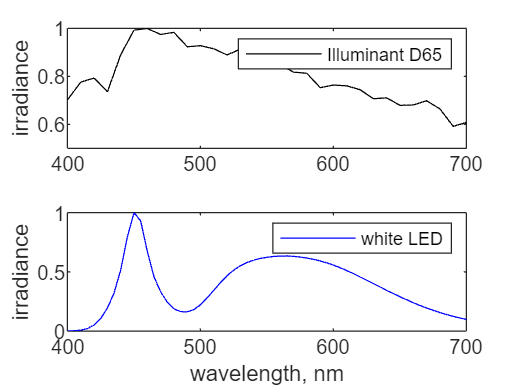

%loading D65, LED, xbar, ybar, zbar in increments of 5 (400-700nm)
illumD65_5 =  readmatrix('Part2.xlsx', 'Range', 'B2:B62');
wavelength_5 = readmatrix('Part2.xlsx', 'Range', 'A2:A62');
whiteLED_5 = readmatrix('Part2.xlsx', 'Range', 'C2:C62');
xbar_5 = readmatrix('Part2.xlsx', 'Range', 'D2:D62');
ybar_5 = readmatrix('Part2.xlsx', 'Range', 'E2:E62');
zbar_5 = readmatrix('Part2.xlsx', 'Range', 'F2:F62');

%Plotting the D65 and LED spectra
figure; 
subplot(2,1,1);
illumD65_5_x = illumD65_5/max(illumD65_5);
plot(wavelength_5, illumD65_5_x,'Color', 'k', 'DisplayName', 'Illuminant D65');
ylabel('irradiance');
legend;
subplot(2,1,2);
plot(wavelength_5, whiteLED_5/max(whiteLED_5), 'Color', 'b','DisplayName', 'white LED');
xlabel('wavelength, nm');
ylabel('irradiance');
legend;
hold off;

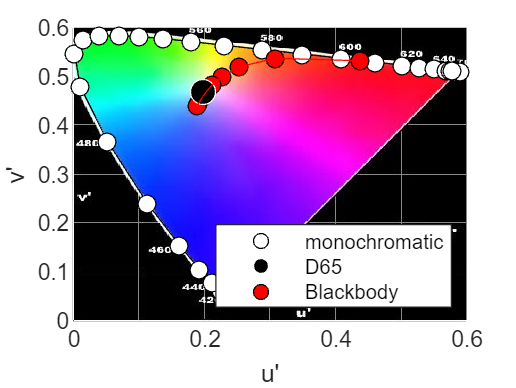

%Getting u' v' from CIE xy of monochromatic light
denominator = - 2 .* all_x + 12 .* all_y + 3;  
u_prime = (4 .* all_x) ./ denominator;
v_prime = (9 .* all_y) ./ denominator;

%Getting u' v' from CIE xy of blackbody
denominatorr = - 2 .* xy_chromaticities(:,1) + 12 .* xy_chromaticities(:,2) + 3; 
u_primee = (4 .* xy_chromaticities(:,1)) ./ denominatorr;
v_primee = (9 .* xy_chromaticities(:,2)) ./ denominatorr;

%tristimulus values of D65 light source
XYZn_D65 = zeros(3,1);
XYZn_D65(1,1) = sum(illumD65_5.*xbar_5);
XYZn_D65(2,1) = sum(illumD65_5.*ybar_5);
XYZn_D65(3,1) = sum(illumD65_5.*zbar_5);

denominator1 = XYZn_D65(1,1) + 15 * XYZn_D65(2,1) + 3 * XYZn_D65(3,1);
u_prime1 = (4*XYZn_D65(1,1)) ./ denominator1;
v_prime1 = (9*XYZn_D65(2,1)) ./ denominator1;

%Plotting in u'v' space
figure;
plot(u_prime, v_prime);
xlim([0 0.6]);
ylim([0 0.6]);
xlabel(" u' ");
ylabel(" v' ");
hold on;
img1 = imread('1976 CIE L''u''v'' - cropped.jpg');
image(img1, 'Xdata', [0 0.6], 'Ydata', [0.6 0]);
plot(u_prime, v_prime, 'k');
xline1 = [0.252964, 0.590909];
yline2 = [0.0604743, 0.511364];
line(xline1, yline2, 'Color', [0 0 0]);
sz = 50;
sz1 = 100;
s2 = scatter(u_prime, v_prime, sz, 'filled', 'DisplayName', 'monochromatic');
s2.MarkerFaceColor = [ 1 1 1 ];
s2.MarkerEdgeColor =  [ 0 0 0 ];
s4 = scatter(u_primee, v_primee, sz, 'filled', 'DisplayName', 'Blackbody');
s4.MarkerFaceColor = [1 0 0];
s4.MarkerEdgeColor = [0 0 0];
s3 = scatter(u_prime1, v_prime1, sz1, 'filled', 'DisplayName', 'D65');
s3.MarkerFaceColor = [0 0 0];
s3.MarkerEdgeColor = [1 1 1];
plot(u_primee, v_primee, 'Color', 'r');

% Create legend with only those scatter plots that have a 'DisplayName'
legend_handles = [s2, s3, s4];
legend_labels = {s2.DisplayName, s3.DisplayName, s4.DisplayName};
legend(legend_handles, legend_labels, 'Location', 'southeast');

hold off;

%load the munsell400_700_5.mat
data = load('munsell400_700_5.mat');
whos("-file", "munsell400_700_5.mat");

  Name            Size               Bytes  Class     Attributes

  C              16x1250            160000  double              
  S            1250x15               37500  char                
  munsell        61x1250            610000  double              




%access munsell matrix
munsell = data.munsell;
S = data.S;
S(400,:)

ans = ' 2_5gV60C04.NM5'


CHIPS = zeros(61,3);
%choosing 3 chips
CHIPS(:,1) = munsell(:,200);
CHIPS(:,2) = munsell(:,400);
CHIPS(:,3) = munsell(:,550);

#### Chips under Illuminant D65

%tristimulus values of chips illuminated by the D65
XYZ_D65 = zeros(3,3);
for i = 1:3
    XYZ_D65(i,1) = sum(illumD65_5.*xbar_5.*CHIPS(:,i));
    XYZ_D65(i,2) = sum(illumD65_5.*ybar_5.*CHIPS(:,i));
    XYZ_D65(i,3)= sum(illumD65_5.*zbar_5.*CHIPS(:,i));
end

%tristimulus values of chips illuminated by white LED
XYZ_LED = zeros(3,3);
for i = 1:3
    XYZ_LED(i,1) =sum(whiteLED_5.*xbar_5.*CHIPS(:,i));
    XYZ_LED(i,2) = sum(whiteLED_5.*ybar_5.*CHIPS(:,i));
    XYZ_LED(i,3)= sum(whiteLED_5.*zbar_5.*CHIPS(:,i));
end

%tristimulus value of white LED
XYZn_LED = zeros(3,1);
XYZn_LED(1,1) = sum(whiteLED_5.*xbar_5);
XYZn_LED(2,1) = sum(whiteLED_5.*ybar_5);
XYZn_LED(3,1) = sum(whiteLED_5.*zbar_5);


%Getting L*a*b*
%L_star(Y,Yn) function: Output L* coordinate 
%a_star(X,Xn,Z,Zn) function: Output a* coordinate
%b_star(Y,Yn,Z,Zn) function: Output b* coordinate
Lab_starr_D65 = zeros(3,3); 
Lab_starr_LED = zeros(3,3);
for i = 1:3
    Lab_starr_D65(i,1) = L_star(XYZ_D65(i,2), XYZn_D65(2,1)); 
    Lab_starr_D65(i,2) = a_star(XYZ_D65(i,1), XYZn_D65(1,1), XYZ_D65(i,3), XYZn_D65(3,1));
    Lab_starr_D65(i,3) = b_star(XYZ_D65(i,2), XYZn_D65(2,1), XYZ_D65(i,3), XYZn_D65(3,1));

    Lab_starr_LED(i,1) = L_star(XYZ_LED(i,2), XYZn_LED(2,1));
    Lab_starr_LED(i,2) = a_star(XYZ_LED(i,1), XYZn_LED(1,1), XYZ_LED(i,3), XYZn_LED(3,1));
    Lab_starr_LED(i,3) = b_star(XYZ_LED(i,2), XYZn_LED(2,1), XYZ_LED(i,3), XYZn_LED(3,1));
end

%Getting the difference 
%deltaE(L1, L2, a1, a2, b1, b2): outputs the color difference 
diff = zeros(3,1);
j = [200, 400, 550];
for i = 1:3
   diff(i,1) = deltaE(Lab_starr_D65(i,1), Lab_starr_LED(i,1), Lab_starr_D65(i,2), Lab_starr_LED(i,2), Lab_starr_D65(i,3), Lab_starr_LED(i,3));
   if diff(i,1) < 2.3 
       fprintf('Chip %s: Color Difference = %3.2f, Not Noticeable Difference\n', S(j(1,i), :), diff(i,1));
   else
       fprintf('Chip %s: Color Difference = %3.2f, Noticeable Difference\n', S(j(1,i), :), diff(i,1));
   end
end

Chip   10rV30C01.NM5: Color Difference = 2.50, Noticeable Difference
Chip  2_5gV60C04.NM5: Color Difference = 4.96, Noticeable Difference
Chip 2_5rpV40C06.NM5: Color Difference = 3.06, Noticeable Difference


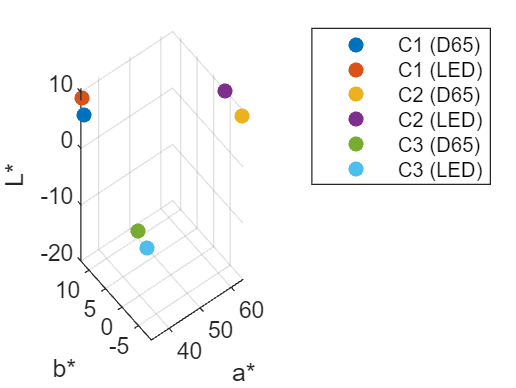

% Create a scatter plot with multiple points in the L*a*b* color space
figure;
scatter3(Lab_starr_D65(1, 1), Lab_starr_D65(1, 2), Lab_starr_D65(1, 3), 'filled', 'DisplayName', 'C1 (D65)');
xlabel('a*');
ylabel('b*');
zlabel('L*');
hold on; 
scatter3(Lab_starr_LED(1,1),Lab_starr_LED(1,2), Lab_starr_LED(1,3), 'filled', 'DisplayName', 'C1 (LED)');
scatter3(Lab_starr_D65(2, 1), Lab_starr_D65(2, 2), Lab_starr_D65(2, 3), 'filled', 'DisplayName', 'C2 (D65)');
scatter3(Lab_starr_LED(2,1),Lab_starr_LED(2,2), Lab_starr_LED(2,3), 'filled', 'DisplayName', 'C2 (LED)');
scatter3(Lab_starr_D65(3, 1), Lab_starr_D65(3, 2), Lab_starr_D65(3, 3), 'filled', 'DisplayName', 'C3 (D65)');
scatter3(Lab_starr_LED(3,1),Lab_starr_LED(3,2), Lab_starr_LED(3,3), 'filled', 'DisplayName', 'C3 (LED)');
% Create legend with only those scatter plots that have a 'DisplayName'
legend;
hold off;

% Convert L*a*b* values to RGB
rgbValues_D65 = zeros(3,3);
rgbValues_LED = zeros(3,3);
for i = 1:3
    labValues_D65 = [Lab_starr_D65(i,1), Lab_starr_D65(i,2), Lab_starr_D65(i,3)];
    labValues_LED = [Lab_starr_LED(i,1),Lab_starr_LED(i,2), Lab_starr_LED(i,3)];
    rgbValues_D65(i,:) = lab2rgb(labValues_D65);
    rgbValues_LED(i,:) = lab2rgb(labValues_LED);
end

% % visualization
% figure;
% x_offset = 0.01; % Set the distance between the patches
% % Patch for D65
% j = patch([0 1 1 0], [0 0 1 1], rgbValues_D65(3,:), 'EdgeColor', 'none');
% hold on;
% % Patch for LED
% k = patch([0 1 1 0] + x_offset, [0 0 1 1], rgbValues_LED(3,:), 'EdgeColor', 'none');
% 
% % Adjust the axis limits for better visualization
% xlim([0 x_offset * 2]); % Set the x-axis limits based on patch positions
% axis off;



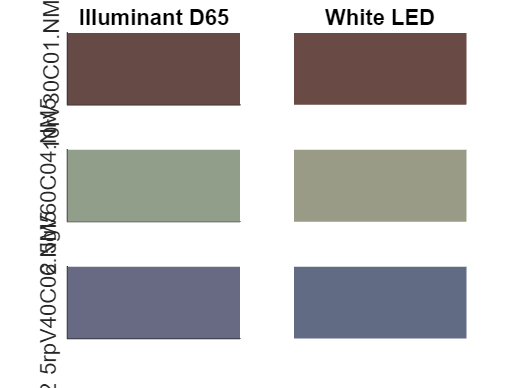


figure;
subplot(3,2,1);
patch([0 1 1 0], [0 0 1 1], rgbValues_D65(1,:), 'EdgeColor', 'none');
title('Illuminant D65');
ylabel('10rV30C01.NM5');
% Remove x-axis ticks and labels
set(gca, 'XTick', []);
set(gca, 'XTickLabel', []);
% Remove y-axis ticks and labels
set(gca, 'YTick', []);
set(gca, 'YTickLabel', []);
subplot(3,2,2);
patch([0 1 1 0], [0 0 1 1], rgbValues_LED(1,:), 'EdgeColor', 'none');
title('White LED');
axis off;
subplot(3,2,3);
patch([0 1 1 0], [0 0 1 1], rgbValues_D65(2,:), 'EdgeColor', 'none');
ylabel('2_ 5gV60C04.NM5');
% Remove x-axis ticks and labels
set(gca, 'XTick', []);
set(gca, 'XTickLabel', []);
% Remove y-axis ticks and labels
set(gca, 'YTick', []);
set(gca, 'YTickLabel', []);
subplot(3,2,4);
patch([0 1 1 0], [0 0 1 1], rgbValues_LED(2,:), 'EdgeColor', 'none');
axis off;
subplot(3,2,5);
patch([0 1 1 0], [0 0 1 1], rgbValues_D65(3,:), 'EdgeColor', 'none');
ylabel('2_ 5rpV40C06.NM5');
% Remove x-axis ticks and labels
set(gca, 'XTick', []);
set(gca, 'XTickLabel', []);
% Remove y-axis ticks and labels
set(gca, 'YTick', []);
set(gca, 'YTickLabel', []);
subplot(3,2,6);
patch([0 1 1 0], [0 0 1 1], rgbValues_LED(3,:), 'EdgeColor', 'none');
axis off;

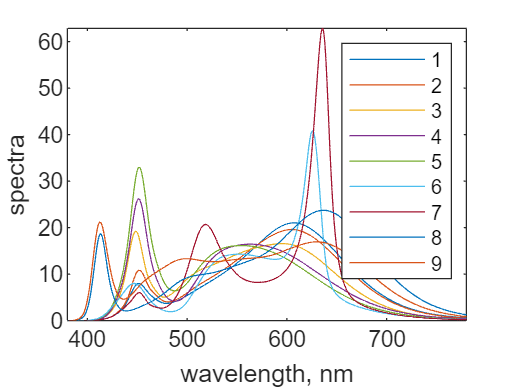

%Visualization
figure;
LED = load('CIE_illum_LEDs_1nm.csv');
for i = 2:10
    plot(LED(:,1), LED(:,i));
    xlim([380 780]);
    xlabel('wavelength, nm');
    ylabel('spectra');
    hold on;
end
legend('1', '2', '3', '4', '5', '6', '7', '8', '9');
hold off;

#### PART 3 OF 3: Color Image Capture and Color Rendering

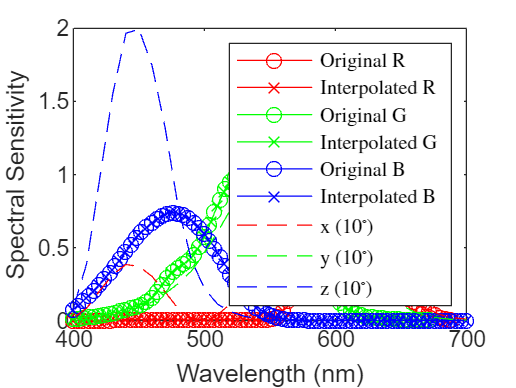

%loading camera sensitivity
R_camera = readmatrix('CANON10D.xlsx', 'Range', 'B2:B77');
G_camera = readmatrix('CANON10D.xlsx', 'Range', 'C2:C77');
B_camera = readmatrix('CANON10D.xlsx', 'Range', 'D2:D77');

% Example data (replace this with your actual data)
wavelength_4nm = 400:4:700; % Wavelength from 380nm to 780nm in 4nm increments

% Define the desired wavelength range with 5nm increments
wavelength_5nm = 400:5:700; % Wavelength from 380nm to 780nm in 5nm increments

% Interpolate the sensitivity data to get the values at 5nm increments
R_camera_5 = interp1(wavelength_4nm, R_camera, wavelength_5nm, 'linear');
G_camera_5 = interp1(wavelength_4nm, G_camera, wavelength_5nm, 'linear');
B_camera_5 = interp1(wavelength_4nm, B_camera, wavelength_5nm, 'linear');

% Plot the original and interpolated data
figure;
plot(wavelength_4nm, R_camera, 'o-','Color', 'r');
hold on;
plot(wavelength_5nm, R_camera_5, 'x-', 'Color', 'r');
plot(wavelength_4nm, G_camera, 'o-', 'Color', 'g');
plot(wavelength_5nm, G_camera_5, 'x-', 'Color','g');
plot(wavelength_4nm, B_camera, 'o-','Color', 'b');
plot(wavelength_5nm, B_camera_5, 'x-', 'Color', 'b');
plot(wavelengths, x_bar, 'r--');
plot(wavelengths, y_bar, 'g--');
plot(wavelengths, z_bar, 'b--');
legend({'Original R', 'Interpolated R', 'Original G', 'Interpolated G', 'Original B','Interpolated B', 'x (10$^\circ$)','y (10$^\circ$)', 'z (10$^\circ$)'  }, 'Interpreter', 'latex');
xlabel('Wavelength (nm)');
xlim([400 700]);
ylabel('Spectral Sensitivity');

legend;

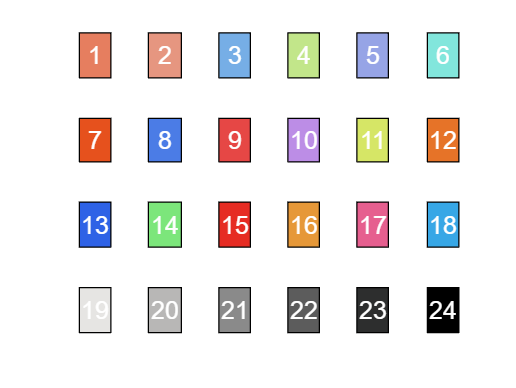

macbeth = zeros(61, 24); % Initialize the 'macbeth' matrix with zeros
letter = ['B', 'C', 'D', 'E', 'F', 'G', 'H', 'I', 'J', 'K', 'L', 'M', 'N', 'O', 'P', 'Q', 'R', 'S', 'T', 'U', 'V', 'W', 'X', 'Y'];

%loading the macbeth patches
for i = 1:24
    range = strcat(letter(i), '8:', letter(i), '68'); % Construct the range string for each iteration
    data = readmatrix('MacbethColorChecker.xls', 'Range', range);
    macbeth(:, i) = data; % Assuming you want to store the first column of each range in 'macbeth'
end

%Getting the DNi per RGB channel
DN = zeros(24,3);
for i = 1:24
    R = DNi(illumD65_5, macbeth(:,i), R_camera_5.');
    G = DNi(illumD65_5, macbeth(:,i), G_camera_5.');
    B = DNi(illumD65_5, macbeth(:,i), B_camera_5.');
    if max([R G B]) == R
        DN(i,1) = double(R/R);
        DN(i,2) = double(G/R);
        DN(i,3) = double(B/R);
    elseif max([R G B]) == G
        DN(i,1) = double(R/G);
        DN(i,2) = double(G/G);
        DN(i,3) = double(B/G);
    else 
        DN(i,1) = double(R/B);
        DN(i,2) = double(G/B);
        DN(i,3) = double(B/B);
    end
end

% Create a grid of colored patches arranged like the Macbeth chart
patch_size = 50;  % Size of each color patch
num_rows = 4;     % Number of rows in the grid
num_cols = 6;     % Number of columns in the grid
figure;
DN(19,:) = DN(19, :) * 1;
DN(20,:) = DN(20, :) * 0.8;
DN(21,:) = DN(21, :) * 0.6;
DN(22,:) = DN(22, :) * 0.4;
DN(23,:) = DN(23, :) * 0.2;
DN(24,:) = DN(24, :) * 0;

brightness_control = 0.9;
for i = 1:num_rows * num_cols
    subplot(num_rows, num_cols, i);
    color = DN(i, :);
    color = max(0, min(1, color)); % Ensure color values are between 0 and 1
    color = color * brightness_control;
    % Plotting the colored patch
    patch([0 patch_size patch_size 0], [0 0 patch_size patch_size], color);
    axis off;
    
    % Adding the patch number as text in the center of the patch
    text(patch_size/2, patch_size/2,  num2str(i), 'Color', 'w', 'HorizontalAlignment', 'center');
end

function L = L_star(Y, Yn)
     if Y/Yn <= (6/29)^3
         L= (29/3)^3 * (Y/Yn);
     else
         L = 116*(Y/Yn)^(1/3) - 16; 
     end
end

function f = F(s)
     if s > (6/29)^3
         f= s^(1/3);
     else
         f = 7.787 * s + (16 / 116); 
     end
end

function a = a_star(X, Xn, Z, Zn)
    a = 500 * (F(X / Xn) - F(Z / Zn));
end

function b = b_star(Y, Yn, Z, Zn)
    b = 500 * (F(Y / Yn) - F(Z / Zn));
end

function E = deltaE(L1, L2, a1, a2, b1, b2)
    E = sqrt( (L2 - L1)^2 + (a2 - a1)^2 + (b2 - b1)^2);
end

function overall = DNi(Plight, Robject, Scamera)
    numerator = sum(Plight.* Robject .* Scamera);
    denominator = sum(Plight .* Scamera);
    overall = numerator / denominator;
end
